Plots to determine if timestep sensitivity is still an issue after changing how ODEs are solved for extracellular reactions.

Uses data files in diagnosis/timesteps

Two features are being changed between the four files

X_glc_X uses a layout that features glucose in the media

X_enz_X uses a layout that includes extracellular reactions for cellulolysis->glucose and enzyme decay

X_X_homebrewRK uses the COMETS-native version of the Runge-Kutta approximation for solving ODES in extracellular reactions

X_X_apacheRK uses the Apache Commons Math version of Runge-Kutta

X_X_apacheGBS uses the Apache Commons Math GraggBulirschStoerIntegrator

As COMETS has been patched, the apache results are stored in folders corresponding to the version number and should be copied into the \timesteps directory before loading

load("C:\sync\biomes\cellulose\optima\diagnosis\timesteps\biodat_glc_homebrewRK.mat");
load("C:\sync\biomes\cellulose\optima\diagnosis\timesteps\biodat_enz_homebrewRK.mat");
load("C:\sync\biomes\cellulose\optima\diagnosis\timesteps\biodat_enz_apacheGBS.mat");
load("C:\sync\biomes\cellulose\optima\diagnosis\timesteps\biodat_glc_apacheGBS.mat");


timesteps = [10 1 .1 .05];
colors = lines(4);

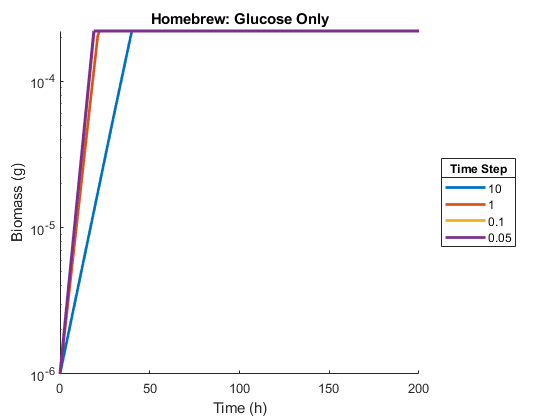

figure();
hold on;
for i = 1:length(biodat_glc_homebrewRK)
    biodat = biodat_glc_homebrewRK{i};
    timestep = timesteps(i);
    t = 0:timestep:200;
    plot(t,biodat,'color',colors(i,:),'LineWidth',2,...
        'DisplayName',num2str(timestep));
end
title('Homebrew: Glucose Only');
leg = legend('location','eastoutside');
title(leg,'Time Step');
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca,'yscale','log');
hold off;

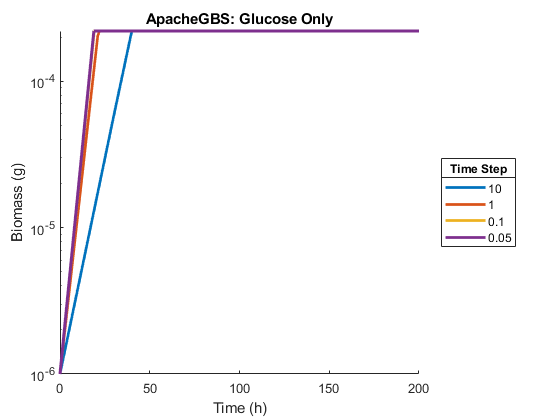

figure();
hold on;
for i = 1:length(biodat_glc_apacheGBS)
    biodat = biodat_glc_apacheGBS{i};
    timestep = timesteps(i);
    t = 0:timestep:200;
    plot(t,biodat,'color',colors(i,:),'LineWidth',2,...
        'DisplayName',num2str(timestep));
end
title('ApacheGBS: Glucose Only');
leg = legend('location','eastoutside');
title(leg,'Time Step');
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca,'yscale','log');
hold off;

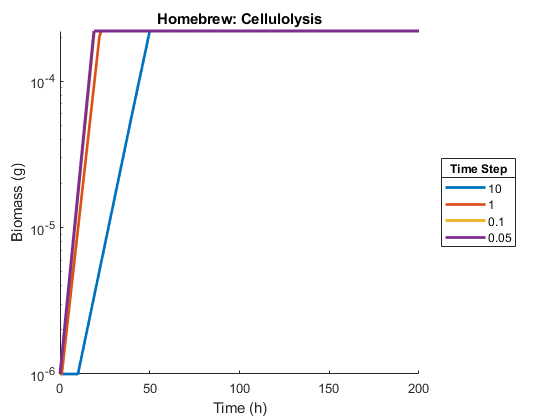

figure();
hold on;
for i = 1:length(biodat_enz_homebrewRK)
    biodat = biodat_enz_homebrewRK{i};
    timestep = timesteps(i);
    t = 0:timestep:200;
    plot(t,biodat,'color',colors(i,:),'LineWidth',2,...
        'DisplayName',num2str(timestep));
end
title('Homebrew: Cellulolysis');
leg = legend('location','eastoutside');
title(leg,'Time Step');
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca,'yscale','log');
hold off;

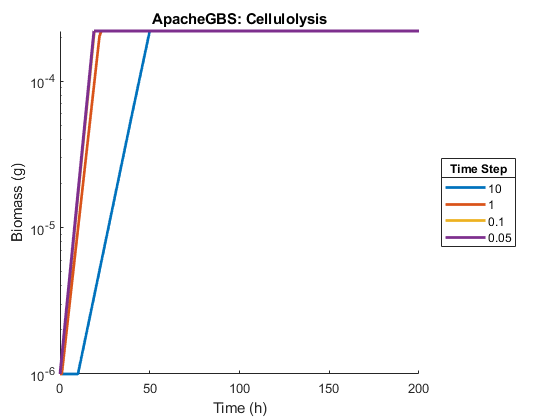

figure();
hold on;
for i = 1:length(biodat_enz_apacheGBS)
    biodat = biodat_enz_apacheGBS{i};
    timestep = timesteps(i);
    t = 0:timestep:200;
    plot(t,biodat,'color',colors(i,:),'LineWidth',2,...
        'DisplayName',num2str(timestep));
end
title('ApacheGBS: Cellulolysis');
leg = legend('location','eastoutside');
title(leg,'Time Step');
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca,'yscale','log');
hold off;

% figure();
% hold on;
% for i = 1:length(biodat_enz_apacheRK)
%     biodat = biodat_enz_apacheRK{i};
%     timestep = timesteps(i);
%     t = 0:timestep:200;
%     plot(t,biodat,'color',colors(i,:),'LineWidth',2,...
%         'DisplayName',num2str(timestep));
% end
% title('ApacheRK: Cellulolysis');
% leg = legend('location','eastoutside');
% title(leg,'Time Step');
% xlabel('Time (h)');
% ylabel('Biomass (g)');
% set(gca,'yscale','log');
% hold off;